# Test FD001


% Read data in
% Pseudo-time series data. Data split into units and time in cycles, which
% both are unknown entities at this point. No idea on what the measurements
% and values truly mean at this point. All data numerical


test_FD001 = readtable("test_FD001.txt");
% Data is cycles over a time per 
variables = test_FD001.Properties.VariableNames;
disp(test_FD001);

    Var1    Var2     Var3       Var4      Var5     Var6      Var7      Var8      Var9     Var10    Var11    Var12     Var13     Var14     Var15    Var16    Var17     Var18     Var19     Var20     Var21    Var22    Var23    Var24    Var25    Var26 
    ____    ____    _______    _______    ____    ______    ______    ______    ______    _____    _____    ______<

summary(test_FD001);

Variables:

    Var1: 13096×1 double

        Values:

            Min           1   
            Median       52   
            Max         100   

    Var2: 13096×1 double

        Values:

            Min           1   
            Median       69   
            Max         303   

    Var3: 13096×1 double

        Values:

            Min       -0.0082 
            Median          0 
            Max        0.0078 

    Var4: 13096×1 double

        Values:

            Min       -0.0006 
            Median          0 
            Max        0.0007 

    Var5: 13096×1 double

        Values:

            Min         100   
            Median      100   
            Max         100   

    Var6: 13096×1 double

        Values:

            Min        518.67 
            Median     518.67 
            Max        518.67 

    Var7: 13096×1 double

        Values:

    

% STD per column
for i = 1:length(variables)
    current_column = test_FD001.(variables{i});
    column_std = std(current_column);
    % Display the standard deviation
    fprintf('STD - %s: %.2f\n', variables{i}, column_std);
end

STD - Var1: 28.29
STD - Var2: 53.06
STD - Var3: 0.00
STD - Var4: 0.00
STD - Var5: 0.00
STD - Var6: 0.00
STD - Var7: 0.40
STD - Var8: 5.00
STD - Var9: 6.69
STD - Var10: 0.00
STD - Var11: 0.00
STD - Var12: 0.68
STD - Var13: 0.06
STD - Var14: 11.44
STD - Var15: 0.00
STD - Var16: 0.20
STD - Var17: 0.56
STD - Var18: 0.06
STD - Var19: 10.19
STD - Var20: 0.03
STD - Var21: 0.00
STD - Var22: 1.23
STD - Var23: 0.00
STD - Var24: 0.00
STD - Var25: 0.14
STD - Var26: 0.08



% Relative large deviations in sensor data for vars
% 14 & 19

 [rows, cols] = size(test_FD001);
disp(['Rows:', num2str(rows)]);

Rows:13096


disp(['Columns: ', num2str(cols)]);

Columns: 26


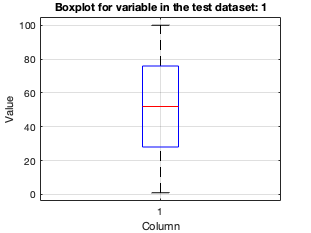

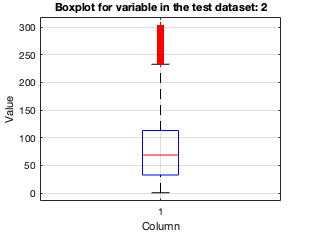

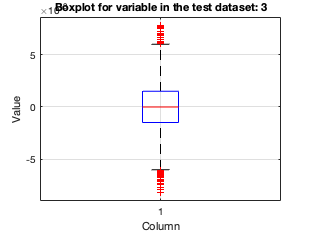

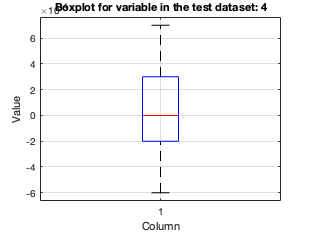

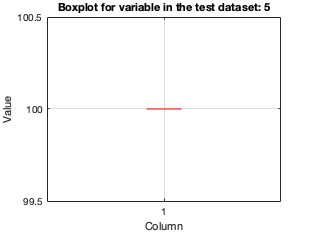

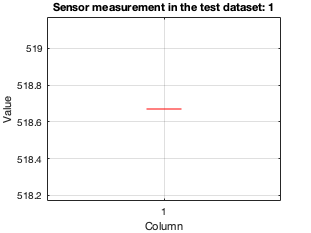

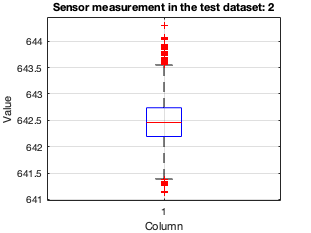

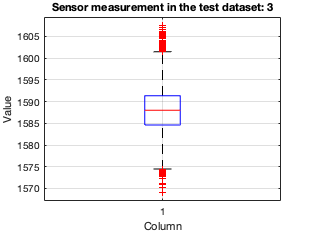

% Boxplots of variables
test_FD001_arr = table2array(test_FD001);

for i = 1:length(test_FD001.Properties.VariableNames)
    figure;
    boxplot(test_FD001.(i),'Positions',i);
    xlabel('Column');
    ylabel('Value');
    title(['Boxplot for variable in the test dataset: ', num2str(i)]);
    if i > 5
        title(['Sensor measurement in the test dataset: ', num2str(i - 5)]);
    end
    grid on;
end

## Train FD 001

% This set contains 1110 observations - Just a vector with no real link to
% the actual dataset. Unsure how to use.
% Read data in
% Pseudo-time series data. Data split into units and time in cycles, which
% both are unknown entities at this point. No idea on what the measurements
% and values truly mean at this point. All data numerical
RUL_FD001 = fileread("RUL_FD001.txt");

train_FD001 = readtable("train_FD001.txt");
% Data is cycles over a time per 
variables = train_FD001.Properties.VariableNames;
% View that data import worked correctly
disp(train_FD001);

    Var1    Var2     Var3       Var4      Var5     Var6      Var7      Var8      Var9     Var10    Var11    Var12     Var13     Var14     Var15    Var16    Var17     Var18     Var19     Var20     Var21    Var22    Var23    Var24    Var25    Var26 
    ____    ____    _______    _______    ____    ______    ______    ______    ______    _____    _____    ______<

summary(train_FD001);

Variables:

    Var1: 20631×1 double

        Values:

            Min           1   
            Median       52   
            Max         100   

    Var2: 20631×1 double

        Values:

            Min           1   
            Median      104   
            Max         362   

    Var3: 20631×1 double

        Values:

            Min       -0.0087 
            Median          0 
            Max        0.0087 

    Var4: 20631×1 double

        Values:

            Min       -0.0006 
            Median          0 
            Max        0.0006 

    Var5: 20631×1 double

        Values:

            Min         100   
            Median      100   
            Max         100   

    Var6: 20631×1 double

        Values:

            Min        518.67 
            Median     518.67 
            Max        518.67 

    Var7: 20631×1 double

        Values:

    

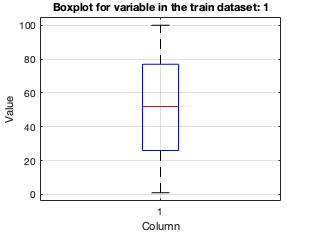

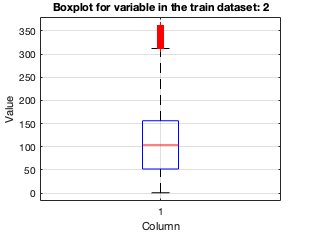

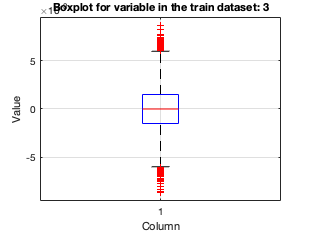

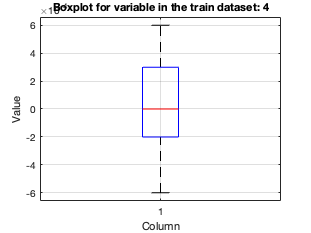

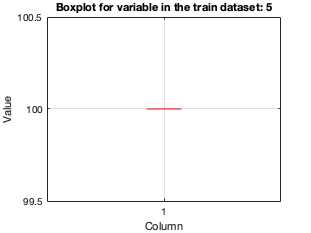

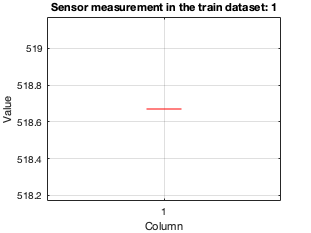

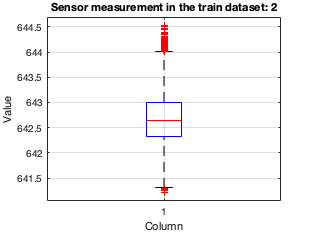

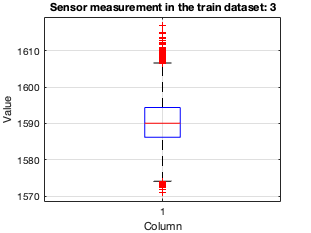

% Boxplots of variables
for i = 1:length(train_FD001.Properties.VariableNames)
    figure;
    boxplot(train_FD001.(i),'Positions',i);
    xlabel('Column');
    ylabel('Value');
    title(['Boxplot for variable in the train dataset: ', num2str(i)]);
    if i > 5
        title(['Sensor measurement in the train dataset: ', num2str(i - 5)]);
    end
    grid on;
end

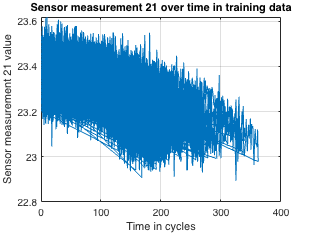

% Lineplot for sensor measurement 21 in training data
figure;
plot(train_FD001.Var2,train_FD001.Var26);
xlabel('Time in cycles');
ylabel('Sensor measurement 21 value');
title('Sensor measurement 21 over time in training data')
grid on;

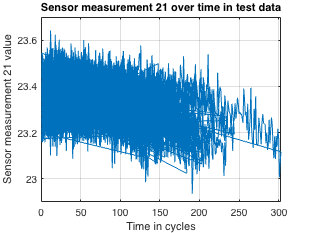

% Lineplot for sensor measurement 21 in test data
figure;
plot(test_FD001.Var2,test_FD001.Var26);
xlabel('Time in cycles');
ylabel('Sensor measurement 21 value');
title('Sensor measurement 21 over time in test data')
grid on;